# **Esercitazione 3 - EMG**

8 prove in 4 condizioni diverse.

Condizione 1 (prove 1 e 2): i soggetti dovevano compiere movimenti piccoli e lenti.

Condizione 2 (prove 3 e 4): movimenti piccoli e veloci.

Condizione 3 (prove 5 e 6): movimenti grandi e lenti.

Condizione 4 (prove 7 e 8): movimenti grandi e veloci.

load("emg_data.mat")

*Obiettivo 1: Estrarre l’inviluppo del segnale EMG per ogni soggetto per ogni prova. *

%uso della funzione get_envelope() 

%frequenza di campionamento
fs = 2000;

[inviluppo, T] = get_envelope (emg_data, fs);


*Obiettivo 2: Normalizzazione del segnale EMG rispetto al massimo valore di ogni soggetto. *

%uso funzione data_normalization()
signal = cell2mat(emg_data(1, 1));
time = signal(:,1);
norm=data_normalization(inviluppo);

*Obiettivo 3: Calcolare lo spettro medio per ogni soggetto per ogni muscolo.*

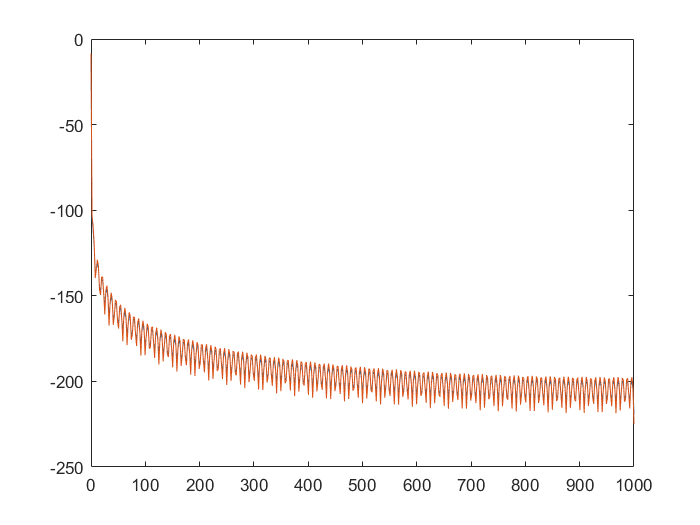

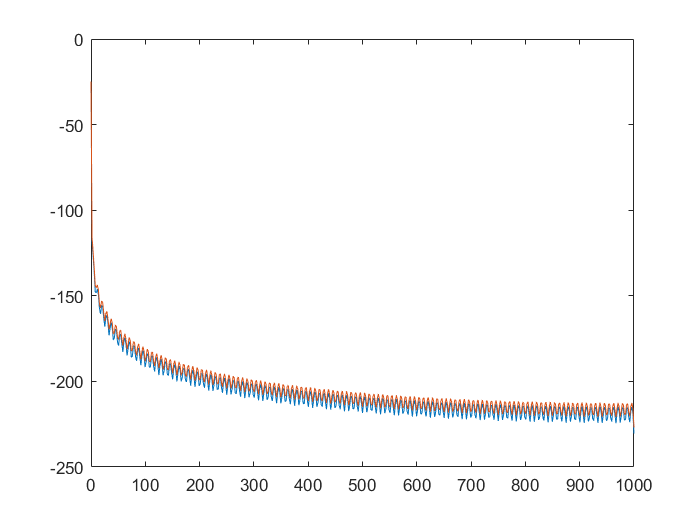

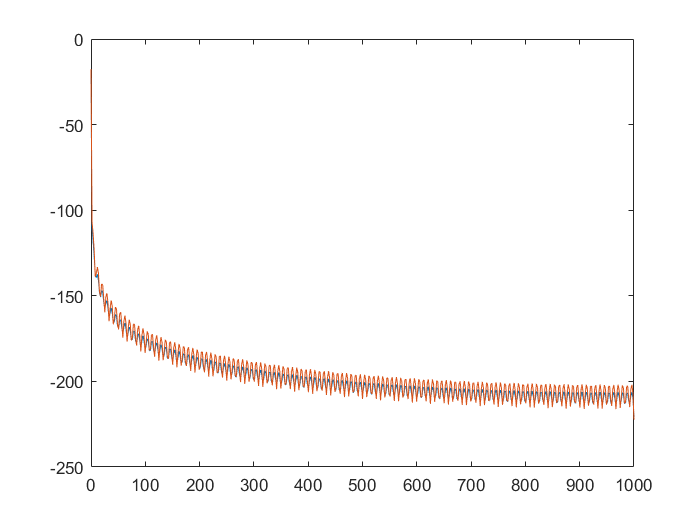

% f = linspace (0, fs/2, floor(nfft/2)+1);
nfft= 2048;
overlap=100;
window=200;
% % 
% % %utilizzo funzione meanpsd() per il calcolo e la visualizzazione dello
% % %spettro di potenza medio di ciascun muscolo di ogni soggetto
 meanpsd(norm,overlap,window,1024,fs)

*Obiettivo 4: Trovare le attivazioni per ogni soggetto e per ogni prova.*

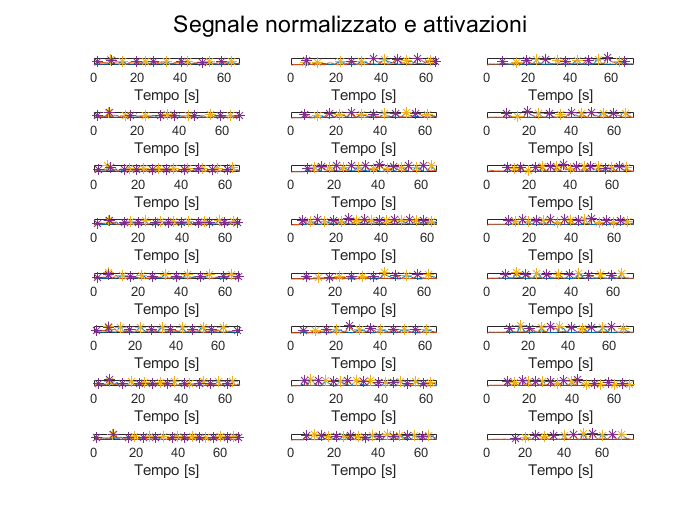

%uso funzione detect_activation()
[num_casi, num_soggetti] = size(norm);

[peaks,time_peaks]=detect_activation(norm, T, 0.25);  

figure
for index_soggetto = 1 : num_soggetti
for index_caso = 1 : num_casi
    subplot(num_casi, num_soggetti, index_soggetto+(index_caso-1)*3)
    
    sgtitle('Segnale normalizzato e attivazioni')
    
    tempo = cell2mat(T(index_caso,index_soggetto));
    dato = cell2mat(norm(index_caso,index_soggetto));
    plot(tempo,dato)
    hold on
    
    tempo_picco1= cell2mat(time_peaks(index_caso,2*index_soggetto-1));
    picco1 = cell2mat(peaks(index_caso,2*index_soggetto-1));
    
    plot(tempo(tempo_picco1),picco1,'*')
    
    hold on
    
    tempo_picco2= cell2mat(time_peaks(index_caso,2*index_soggetto));
    picco2 = cell2mat(peaks(index_caso,2*index_soggetto));
    
    plot(tempo(tempo_picco2),picco2,'*')
    
    xlabel('Tempo [s]')
    ylabel('Ampl. [a.u]')
    
    hold off
end
end

*Obiettivo 5: Visualizzazione delle singole attivazioni nelle 4 condizioni.*

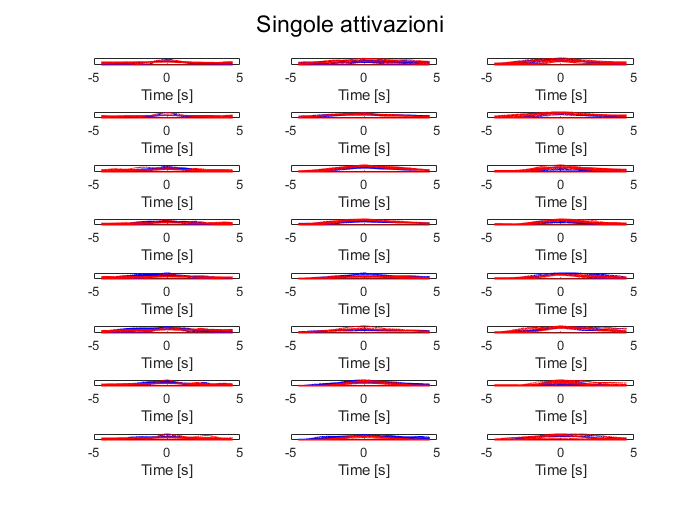

single_peaks=cell(num_casi, 2*num_soggetti);

M=9000;

figure

axes= linspace(-M/2, M/2, M+1)/ (fs/2);

for index_soggetto = 1 : num_soggetti
for index_caso = 1 : num_casi
    
    tempo_picco1= cell2mat(time_peaks(index_caso,2*index_soggetto-1));
    tempo_picco2= cell2mat(time_peaks(index_caso,2*index_soggetto));
    dato = cell2mat(norm(index_caso,index_soggetto));
    
    
    %in alcuni casi vengono tolti i picchi agli estremi perchè sennò
    %schifo, si va troppo oltre
    if(index_soggetto==1 || index_soggetto==2)
        tempo_picco2=tempo_picco2(2:end-1);
        
    end
    if(index_soggetto==3)
        tempo_picco1=tempo_picco1(2:end-1);
    end
    
    singolo_picco1=zeros(M+1, length (tempo_picco1));
    singolo_picco2=zeros(M+1, length (tempo_picco2));
    
    subplot(num_casi, num_soggetti, index_soggetto+(index_caso-1)*3)
    
    sgtitle('Singole attivazioni')
    
    for index_picco1 = 1 : length (tempo_picco1)
    singolo_picco1 (:, index_picco1) = dato(tempo_picco1(index_picco1)-(M/2): tempo_picco1(index_picco1)+(M/2),1 ) ;
    plot(axes, singolo_picco1, 'color', 'b')
    hold on
    end
    
    for index_picco2 = 1 : length (tempo_picco2)
    singolo_picco2(:, index_picco2) = dato(tempo_picco2(index_picco2)-(M/2): tempo_picco2(index_picco2)+(M/2),2 ) ;
    plot(axes, singolo_picco2, 'color', 'r')
    hold on
    end
    
    xlabel('Time [s]')
    ylabel('Aumpl. [a.u]')
    
    single_peaks{index_caso, 2*index_soggetto-1} = singolo_picco1;
    single_peaks{index_caso, 2*index_soggetto} = singolo_picco2;

end
end

*Obiettivo 6: calcolare e visualizzare la durata di attivazione media per ogni soggetto e per ogni prova.*

uso full_width at half maximum

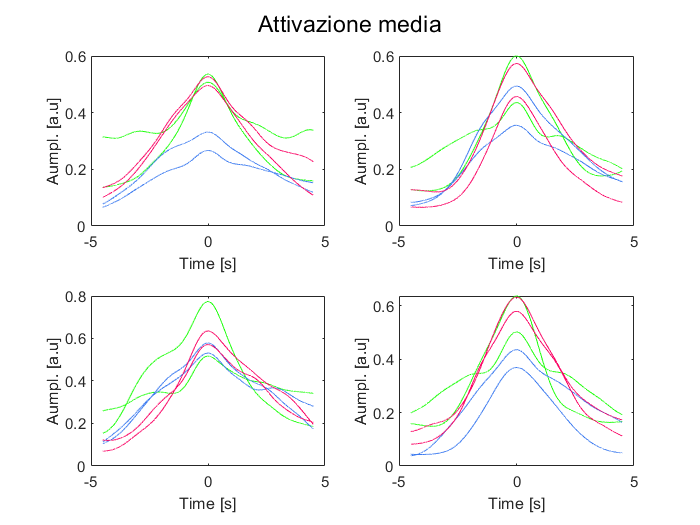

figure

%preallocazione matrici che conterranno i valori dei muscoli nelle prove
prova_m1 = zeros(M+1, 2);
prova_m2 = zeros(M+1, 2);

widths=zeros(num_casi/2, 2* num_soggetti);

%cell array contenente i colori associati ai soggetti
colors={'#1FFF0D'  '#3E7CF0'  '#FA0565'};

for index=1: num_casi/2
for index_sogg=1:num_soggetti
    
    prova_m1 (:,1) = mean (cell2mat(single_peaks(2*index-1, 2*index_sogg-1)),2);
    prova_m1 (:,2) = mean (cell2mat(single_peaks(2*index, 2*index_sogg-1)),2);
    
    %così prendo prova 1, muscolo 2 di ogni soggetto
    prova_m2 (:,1) = mean (cell2mat(single_peaks(2*index-1, 2*index_sogg)),2);
    prova_m2 (:,2) = mean (cell2mat(single_peaks(2*index, 2*index_sogg)),2);
    
    mean_act1=mean(prova_m1,2);
    mean_act2=mean(prova_m2,2);
    
    
    thr1=mean(mean_act1)+std(mean_act1)*0.25;
    thr2=mean(mean_act2)+std(mean_act2)*0.25;
    
    [~,~, widths(index, 2* index_sogg -1)]= findpeaks(mean_act1,'MinPeakHeight',thr1);
    [~,~, widths(index, 2* index_sogg)]= findpeaks(mean_act2,'MinPeakHeight',thr2);
    
    subplot(2,2, index)
    
    sgtitle('Attivazione media')
    plot(axes, mean_act1, 'color', colors{index_sogg})
    hold on
    plot(axes, mean_act2, 'color',  colors{index_sogg})
    hold on
    
    xlabel('Time [s]')
    ylabel('Aumpl. [a.u]')
    

end
end

%visualizzazione dei valori della durata di attivazione media
widths

widths = 	1.0e+03 *

    2.5655    2.0231    3.0059    4.2526    4.0445    3.2115
    2.6672    3.1957    3.8147    3.5880    2.8027    3.0129
    3.7377    1.9416    2.7372    4.3627    3.3441    3.4452
    2.5818    3.1501    3.5416    3.2532    3.6547    3.0019


*Obiettivo 7: Effettuare un permutation test sui dati tramite l'utilizzo di una funzione.*

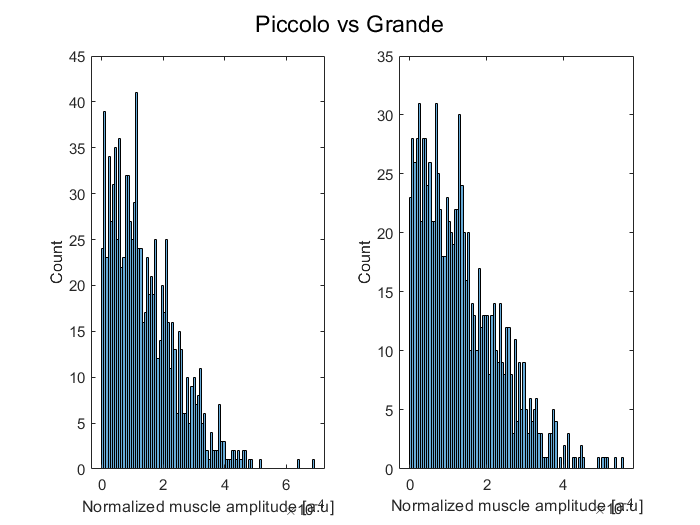

%uso funzione my_permutation_test() 

piccolo=zeros(length(cell2mat(norm(1:4,1)))+length(cell2mat(norm(1:4,2)))+length(cell2mat(norm(1:4,3))),2);
grande=zeros(length(cell2mat(norm(5:8,1)))+length(cell2mat(norm(5:8,2)))+length(cell2mat(norm(5:8,3))),2);
index_p=cumsum ([1, length(cell2mat(norm(1:4,1))), length(cell2mat(norm(1:4,2))), length(cell2mat(norm(1:4,3)))]) ;
index_g=cumsum ([1, length(cell2mat(norm(5:8,1))), length(cell2mat(norm(5:8,2))), length(cell2mat(norm(5:8,3)))]) ;

lento=zeros(length(cell2mat(norm([1,2,5,6],1)))+length(cell2mat(norm([1,2,5,6],2)))+length(cell2mat(norm([1,2,5,6],3))),2);
veloce=zeros(length(cell2mat(norm([3,4,7,8],1)))+length(cell2mat(norm([3,4,7,8],2)))+length(cell2mat(norm([3,4,7,8],3))),2);
index_l=cumsum ([1, length(cell2mat(norm([1,2,5,6],1))), length(cell2mat(norm([1,2,5,6],2))), length(cell2mat(norm([1,2,5,6],3)))]) ;
index_v=cumsum ([1, length(cell2mat(norm([3,4,7,8],1))), length(cell2mat(norm([3,4,7,8],2))), length(cell2mat(norm([3,4,7,8],3)))]) ;


for index_sogg=1:num_soggetti
       
    piccolo(index_p(index_sogg):index_p(index_sogg+1)-1,:)=cell2mat(norm(1:4,index_sogg));
    grande(index_g(index_sogg):index_g(index_sogg+1)-1,:)=cell2mat(norm(5:8,index_sogg));
    
    lento(index_l(index_sogg):index_l(index_sogg+1)-1,:)=cell2mat(norm([1,2,5,6],index_sogg));
    veloce(index_v(index_sogg):index_v(index_sogg+1)-1,:)=cell2mat(norm([3,4,7,8],index_sogg));
      
end


p_value_GvsP = my_permutation_test(piccolo', grande', 1000, 'Piccolo vs Grande');

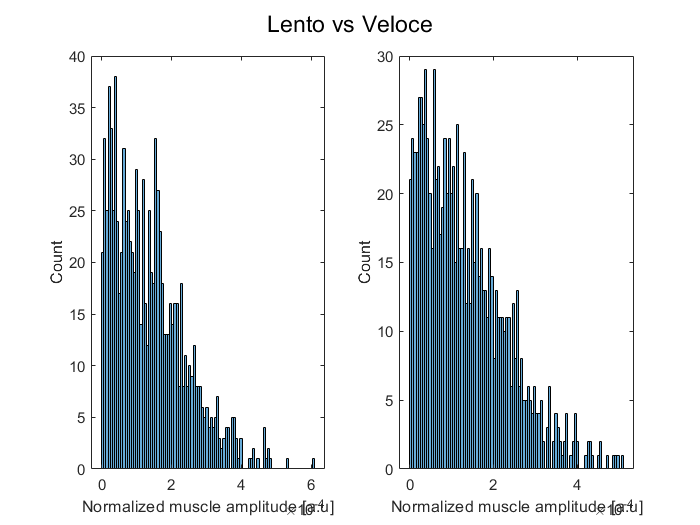

p_value_LvsV= my_permutation_test(lento', veloce', 1000, 'Lento vs Veloce');